# MATLAB 101

#### Crash Course for Beginners

`///////////////////////////////////////`

### FINAL PROJECT

#### Total Marks : 50

`In this project you will develop an image processigng algorithm which will take the image of a ``Bangladeshi Currency Note`` as input and output it's ``value``. `

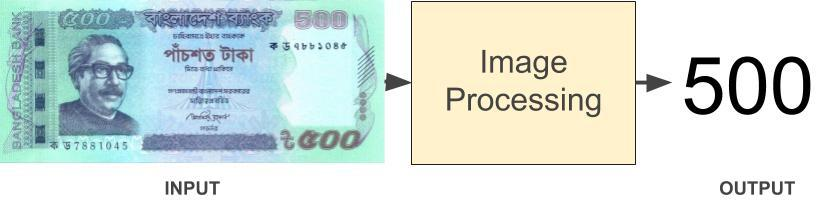

`Image samples of all the Bangladeshi have been provided in this directory. `

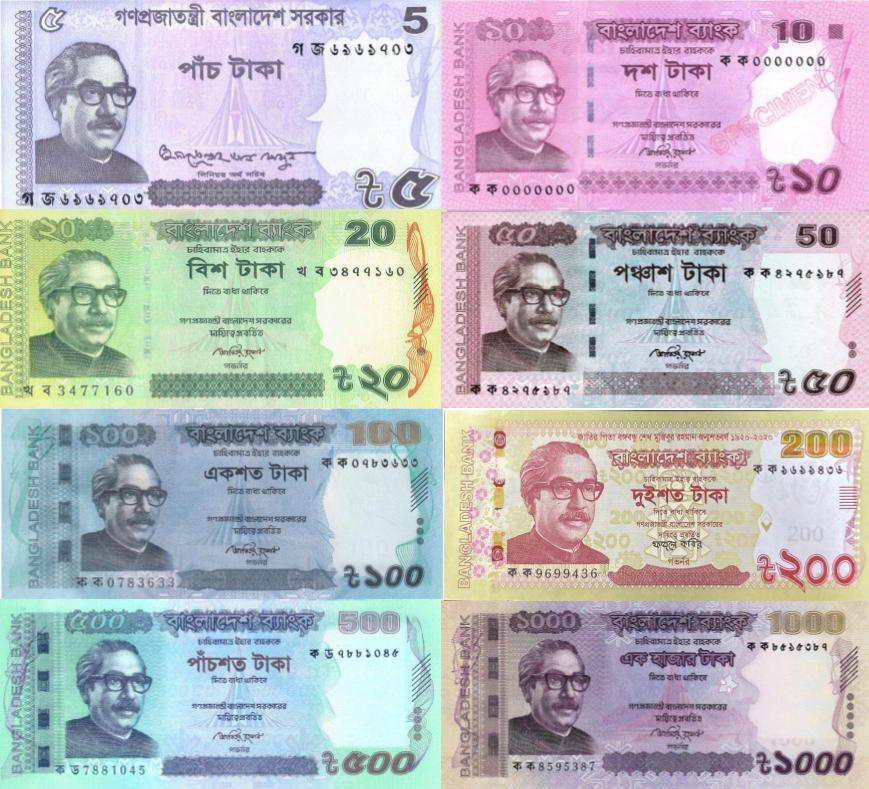

### TASK 1 : Loading Image

`Use the ``imread(filename)`` function to read an image from the file. Store the result in a matrix called ``I``. Then display the image using ``imshow()``. For ``'1000.jpg'`` the result should look like this:`

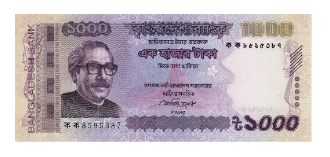

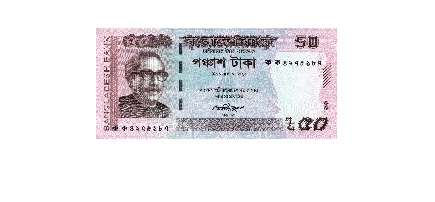

% CHANGE THE FILE NAME HERE TO LOAD
% DIFFERENT IMAGE
filename = '50.jpg';

% LOAD IMAGE
I = imread(filename);

% DISPALY IMAGE
imshow(I);

### TASK 2 : Resize

`The images are not of the same size. Or in other words the matrix dimension for all the note images are not the same. So before any further processing step you need to ``resize the images`` so that they all have the same shape. Use can use ``imresize()`` function to accomplish that. Using this function resize the input image`

`so that it is ``880px wide and 400px tall``. (``Resulatnt matrix size should be 400x800x3``).`

resized = imresize(I, [400, 880]);

### TASK 3 : Crop Region of Interest

`In this problem we are only interested to the part of the note where it's value is printed. So in this section you will crop out that area from rest of the image. You can use ``imcrop()`` function to do that. Using this function crop out the lower right hand corner of the image where the value is printed.`

`The output should look something like this:`

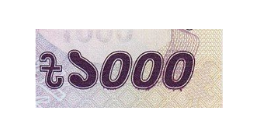

`Note :`` The x, y co-odinates and the width and height of the cropped section should be ``same`` for every image. So make sure that your parameters ``generalize`` for all images.`

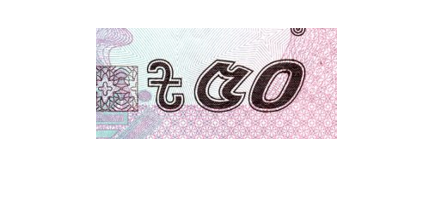

cropped = imcrop(resized, [640, 290, 240, 110]);
imshow(cropped);

### TASK 4 : Convert to Grayscale

`Next you need to convert the resized image from RGB to grayscale. You can use ``rgb2gray()`` function to accomplish that. The result should look like below:`

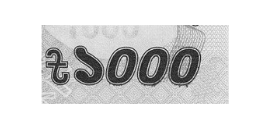

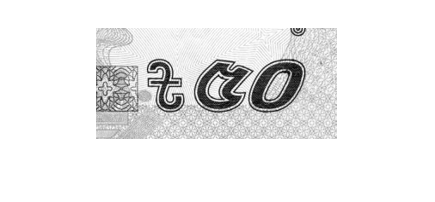

gray = rgb2gray(cropped);
imshow(gray);

### TASK 5 : Enhance the Contrast

`In the next steps you will extract the text from this grayscale image. But before doing that it might be useful to increase the contrast of this image so that it is clearer. You can use the ``imadjust()`` function to improve the contrast. The result should look like this:`

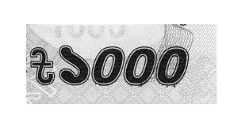

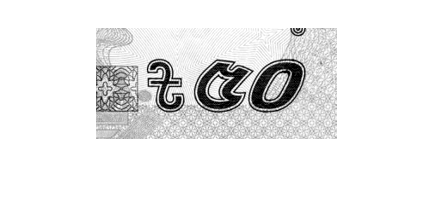

adjusted = imadjust(gray);
imshow(adjusted);

### TASK 6 : Convert to Binary Image

`In this step you will convert this image into a binary image so that it only contains 0s and 1s. You can do that by first calculating ``threshold`` using the ``graythresh()`` function and then passing the threshold value into the ``imbinarize()`` funtion. Perform a ``"not"`` operation on the output so that the background is black and the foreground is white. The result should look like this :`

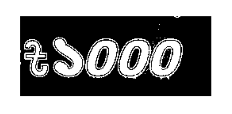

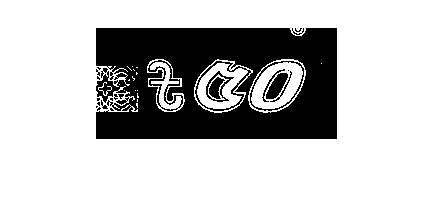

threshold = graythresh(adjusted);
bin = ~ imbinarize(adjusted, threshold);
imshow(bin);

### TASK 7 : Filling the Gaps

`In this step you will remove the outlines from the letters and remove the ``holes`` from the zeros. You can use the ``imfill()`` function to do that. The result should look like this :`

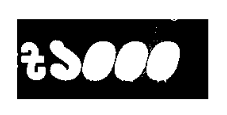

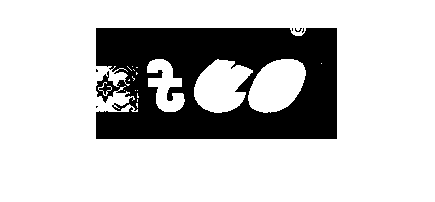

filled = imfill(bin, 'holes');
imshow(filled);

### TASK 8 : Cleaning Up

`There is still a lot of noise left in the image. You can clean this up using the ``bwareaopen()`` function. Play around with the pixel parameter so that it works for every single image. The result should look similar to this:`

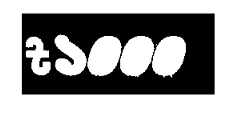

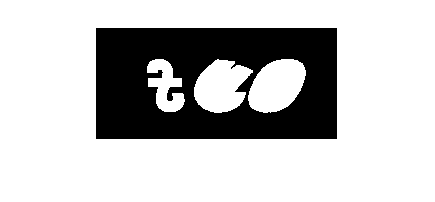

cleaned = bwareaopen(filled, 900);
imshow(cleaned);

`There still might be some some noise left in some of the images like this one:`

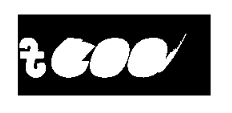

`You can improve this by creating a structuring element using ``strel()`` function and then passing the structring object into the ``imopen()`` function. Play around with the structure shape and size so that it provides the best result for all images. For the 500 taka note the result should look similar to this: `

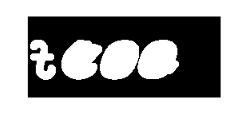

`You can call ``bwareaopen() again`` after this again to further cleanup the image.`

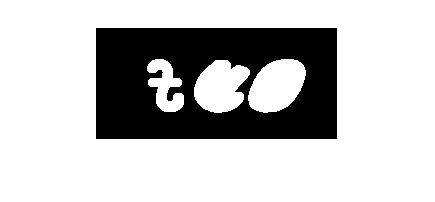

SE = strel('disk', 5);
cleaned = imopen(cleaned, SE);
imshow(cleaned);


cleaned = bwareaopen(cleaned, 400);
imshow(cleaned);

`NOTE : ``SAVE THE RESULTANT IMAGE FROM THIS SECTION INTO A VARIABLE CALLED`` '``cleaned``'. ``THIS NAME WILL BE USED IN THE NEXT SECTION.`

### TASK 9 : Drawing Bounding Boxes

`In this section we will draw bounding boxes around the individual letters. We will use the functions ``bwabel()`` and ``regionprops()`` for this task. The result should look similar to this:`

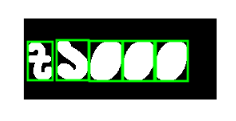

`NOTE:`` The code for this section has been already compleated for you. Please go through the code and try to understand it. You ``DON'T`` need to add any code here.`

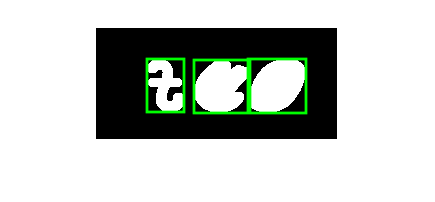

imshow(cleaned);

hold on;

% LABEL THE INDIVIDUAL OBJECTS IN THE IMAGE
% L IS THE LABEL MATRIX AND N IS THE NUMBER OF OBJECTS
[L, N] = bwlabel(cleaned);

% GET THE BOUNDING BOX COORDINATES
boxes = regionprops(L, 'BoundingBox');
% THE BOX OBJECTS CONTAINS 4 PARAMETERS
%   1. TOP LEFT CORNER X
%   2. TOP LEFT CORNER Y
%   3. BOX WIDTH
%   4. BOX HEIGHT

% DRAW THE BOUNDING BOXES
for i = 1 : N
    rectangle('Position',boxes(i).BoundingBox,...
        'EdgeColor','g','LineWidth',2)
end

hold off;

`Next we will combine all the bounding boxes into a single box. The result should look like the following :`

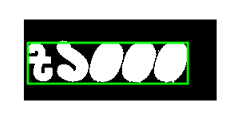

`This section has been already completed for you. Go through the code and try to understand it. You ``DON'T`` need to add any code here.`

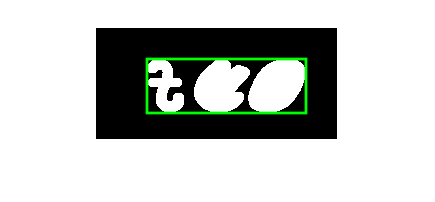

% X COORDINATE OF THE FIRST BOX TOP LEFT CORNER
start_x = boxes(1).BoundingBox(1);

% Y COORDINATE OF THE FIRST BOX TOP LEFT CORNER
start_y = boxes(1).BoundingBox(2);

% X COORDINATE OF THE LAST BOX BOTTOM RIGHT CORNER
end_x = boxes(end).BoundingBox(1) + ...
    boxes(end).BoundingBox(3);

% Y COORDINATE OF THE LAST BOX BOTTOM RIGHT CORNER
end_y = boxes(end).BoundingBox(2) + ...
    boxes(end).BoundingBox(4);

% CALCULATING WIDTH
width = end_x - start_x;

% CALCULATING HEIGHT
height = end_y - start_y;

imshow(cleaned);

hold on;

% DRAWING THE BOUNDING BOX
rectangle('Position', [start_x, start_y, width, height],...
        'EdgeColor','g','LineWidth',2);
    
hold off;

### TASK 10 : Crop Out The Region of Interset

`In this section you will crop out the section inside the final bounding box. You can use the ``imcrop()`` function with the ``start_x, start_y, width, height`` parameters calculated in the previous section. The result should look similar to this:`

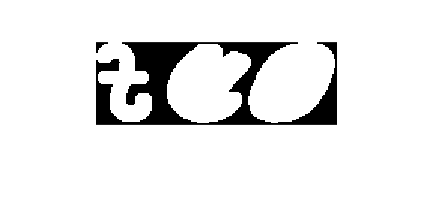

roi = imcrop(cleaned, [start_x, start_y, width, height]);
imshow(roi)

###  TASK 11 : 

`Next you need to ``resize`` the cropped region of interest so that region of interests from all images have the same size. You can use ``imresize()`` for that.`

`Resize the image so that it has a width of ``150px`` and height of` `50px``.`

`The result should look like the following:`

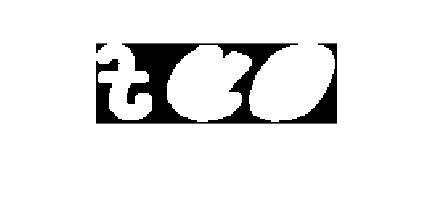

final = imresize(roi, [50, 150]);
imshow(final); 

### FINAL TASK : Finding Match

`In this section you will ``compare`` your image with the base images in the 'base' directory. This directory contains standard region of interests for all the notes that you can compare with to find the best match.`

`The images in the 'base' directory are labelled with their corresopnding note values. The base images look like these:`

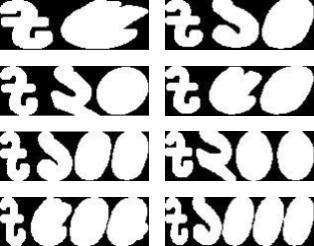

`You will use the ``corr2()`` funtion to calculate the ``correlation`` between your image and the base image. The higher the correlation value the greater the ``similarity``. If the similarity value is higher than a set ``threshold`` you can declare your image to be same as the base. You will need to play around with the threshold value to fugure out what works best. `

`Once you have your result you can display the input note image with ``title`` of it's value that you found out.`

`The result should look similar to this:`

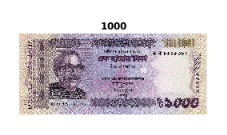

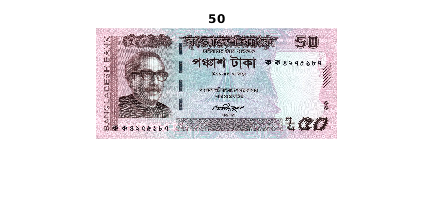

notes = ["5", "10", "20", "50", ...
    "100", "200", "500", "1000"];

% YOU NEED TO SET THE THRESHOLD VALUE HERE
threshold = 0.9;

imshow(I);

% THIS LOOPS THROUGH ALL THE IMAGES IN THE BASE DIRECTORY
% AND LOADS THEM INTO base_image VARIABLE
% YOU CAN PERFORM A CORRELATION OPERATION BETWEEN
% YOUR IMAGE AND THIS base_image TO CALCULATE THE SIMILARITY
% THEN YOU CAN USE A IF STATEMENT TO CHECK IF THE
% SIMILARITY IS GREATER THEAN THE THRESHOLD
% IF THATS THE CASE THEN SET THE TITLE OF THE 
% INPUT IMAGE WITH IT'S VALUE

for i = 1 : length(notes)
    base_image = imread(strcat('base/', notes(i), '.jpg'));
    % YOUR CODE HERE
    similarity = corr2(final, base_image);
    if(similarity > threshold)
        title(notes(i))
    end
end

**Congratulations! **

You Developed an image processing algorithm to detect the value of any Bangladeshi currency from it's image.

### THANK YOU!